# **Big Question:**

## How do the factors of vaccination and death effect disease?

We are asking this question to gain a better understanding of the SIRVD model. We arent looking for a specific numerical answer, instead our aim is to interpret broad trends in our simulations. Seeing the direct effects of these variables can be used to inform disease response. In order to build our models we'll have to understand the math behind the SIRVD and SIRS models.

### **Research Matrix**

# **Methodology:**

The plan is as follows:

- Implement the SIRS model and the SIRVD model

- Perform parameter sweeps over all variables for both model

- Compare and interpret thedata to see the effects of vaccination and death

# **Model:**

We will implement the SIRVD model and adapt it as the SIRS model. We have drawn a tenchi diagram that shows the boundry od the natural world:

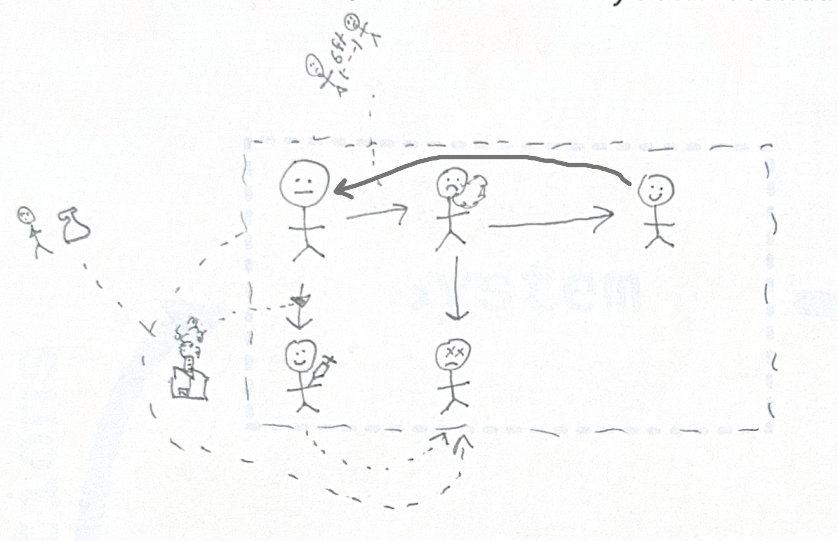

For a clearer view of whats going on we have a stock and flow model:

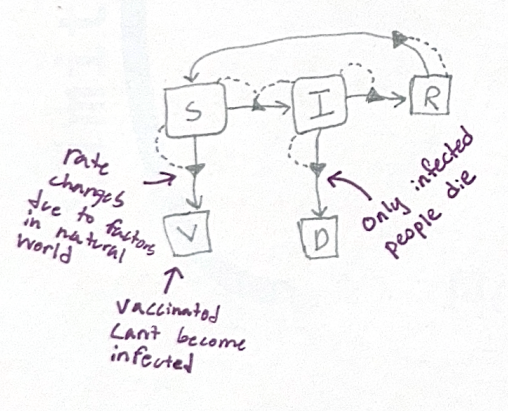

- S = Susceptible

- I = Infected

- R = Recovered

- V = Vaccinated

- D = Dead

As noted in the diagram, our model is subject to certain limitations:

- Only infected people die. In the real world all groups have an additional miniscule chance of dying at all times. The parameters typically used for this chance are extremely small (<2x10^-5) and given this parameter will not be a factor in either the SIRVD or SIRS model it can safely be disregarded

- Vaccinated people can't become infected. In reality vaccine effectiveness can differ between people and wear off. While this may make our models less useful for looking at raw number statistics, the effect that vacines have will remain the same in principle

- Vaccine rate only changes based on the number of susceptible people. There are many external factors in the real world that can contribute to vaccination rates. These include funding for programs, development time, and manufacturability. While this could be useful information, it's not necessary to see the effects of vaccination in general.

## **Implementation:**

First lets take a look at the SIRS model. This is a model primarily used for modeling infectious diseases. The name SIRS comes from the stocks that are used in the model. These being people that are **S**usceptible, **I**nfectious, **R**ecovered, and **S**usceptible (again). The reason susceptible appears twice is to take into account recovered indivicuals becoming re-susceptible.

Here is a simple implementation of the SIRS model:

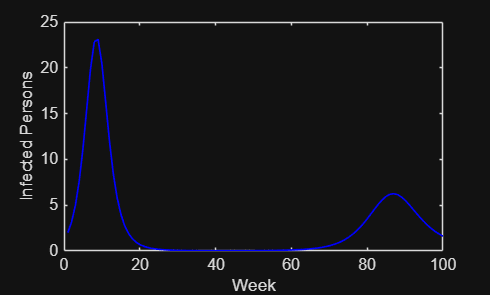

% Configure the simulation
beta = 1 / 90;                   % Infection rate
gamma = 1 / 2;                  % Recovery rate
alpha = 1/60;                    % Resuseptible Rate
week_end = 100;              % Weeks to simulate
i_1 = 2;                             % Initial count of infected persons
s_1 = 100 - i_1;                 % Initial count of susceptible persons
r_1 = 0;                             % Initial count of recovered persons

% Run simulation
[S_long, I_long, R_long, W_long] = simulate_sirs(s_1, i_1, r_1, beta, gamma, alpha, week_end);

% Plot the fitted simulation
figure()
plot(W_long, I_long, 'b-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
xlabel("Week")
ylabel("Infected Persons")
hold off

This model can be overlaid with a dataset to anecdotally show its accuracy:

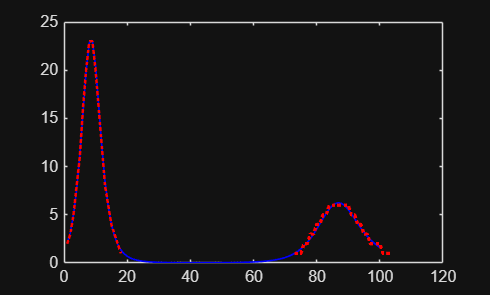

% Load the training + validation data
tab_data = readtable("infected.csv", "Delimiter", ",");
W_data = tab_data.Week;
I_data = tab_data.InfectedCount;
tab_data_validate = readtable("wave1.csv", "Delimiter", ",");

% Plot the model + data
plot(W_long, I_long, 'b-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
plot(tab_data_validate.Week, tab_data_validate.InfectedCount, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Wave 1')
plot(tab_data_wave2.Week, tab_data_wave2.InfectedCount, 'r:', 'LineWidth', 2.0, 'DisplayName', 'Wave 2')

Noteably this model can show a second wave of infections due to recovered individuals becoming re-susceptible.

*explain the step function of SIRS here*

Now for the SIRVD model. Similar to the SIRS model the SIRVD model takes into account people becoming re-susceptible. The main difference is the additional variables for **V**accinations and **D**eaths. By adding these stocks in we are able to see more complex behavior.

This is the code for one step of the SIRVD model:

%put the step here

In order to verify our model works we run a few tests using arbitrary data

- Does the population ever go up?

%code to check with assert() statement

        2.  Does the infection spread in a 100% vaccinated group?

%code to check with assert() statement

        3. NEED MORE VERIFICATION STEPS

With the model implemented and verified we needed to decide on parameters such as infection rate, mortality rate, etc. and starting conditions. ?SHOULD WE USE REAL DISEASE DATA? With our parameters set we can run all the models, performing parameter sweeps on vaccination rate and mortality rate

%run simulations but dont graph them

# **Results:**

Ok i dont really undersand the metrics.

We need to run the model to make this section

# **Interpretation:**

% Load the training + validation data
tab_data = readtable("infected.csv", "Delimiter", ",");
W_data = tab_data.Week;
I_data = tab_data.InfectedCount;
tab_data_validate = readtable("wave1.csv", "Delimiter", ",");
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");

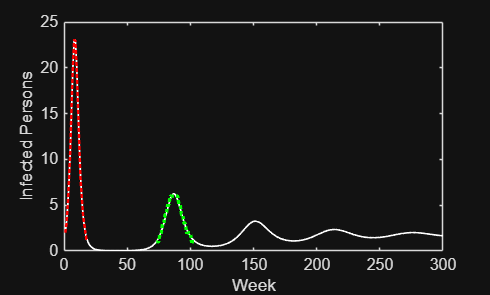

% Configure the simulation
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
alpha = 1/60; % Resuseptible Rate
% week_end = 100;
week_end = 300;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;

% Run simulation
[S_sirs, I_sirs, R_sirs, W_sirs] = simulate_sirs(s_1, i_1, r_1, beta, gamma, alpha, week_end);

% Plot the fitted simulation
figure()
plot(W_sirs, I_sirs, 'w-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRS'); hold on
plot(tab_data_validate.Week, tab_data_validate.InfectedCount, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Wave 1')
plot(tab_data_wave2.Week, tab_data_wave2.InfectedCount, 'g:', 'LineWidth', 2.0, 'DisplayName', 'Wave 2')
xlabel("Week")
ylabel("Infected Persons")

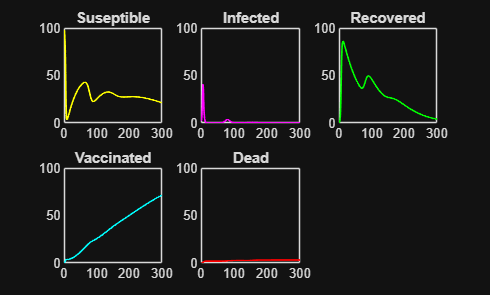

v_1 = 0;
d_1 = 0;

beta = 1/60;
gamma = 1/2;
alpha = 1/60;
sigma = 1/120;
p = 1/50;

[S_sirvd, I_sirvd, R_sirvd, V_sirvd, D_sirvd, W_sirvd] = simulate_sirvd(s_1, i_1, r_1, v_1, d_1, beta, gamma, alpha, sigma, p, week_end);

T_sirvd = S_sirvd + I_sirvd + R_sirvd + V_sirvd + D_sirvd;
assert(all(T_sirs-100 < 1e-10))

figure()
subplot(2, 3, 1)
plot(W_sirvd, S_sirvd, 'y-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Suseptible')

subplot(2, 3, 2)
plot(W_sirvd, I_sirvd, 'm-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Infected')

subplot(2, 3, 3)
plot(W_sirvd, R_sirvd, 'g-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Recovered')

subplot(2, 3, 4)
plot(W_sirvd, V_sirvd, 'c-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Vaccinated')


subplot(2, 3, 5)
plot(W_sirvd, D_sirvd, 'r-', 'LineWidth', 1, 'DisplayName', 'Simulated SIRVD'); hold on
ylim([0 100])
title('Dead')

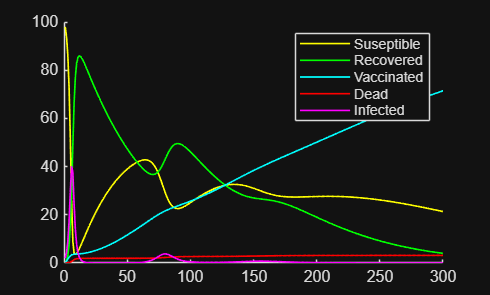

figure()
hold on
plot(W_sirvd, S_sirvd, 'y-', 'LineWidth', 1, 'DisplayName', 'Suseptible');
plot(W_sirvd, R_sirvd, 'g-', 'LineWidth', 1, 'DisplayName', 'Recovered');
plot(W_sirvd, V_sirvd, 'c-', 'LineWidth', 1, 'DisplayName', 'Vaccinated');
plot(W_sirvd, D_sirvd, 'r-', 'LineWidth', 1, 'DisplayName', 'Dead');
plot(W_sirvd, I_sirvd, 'm-', 'LineWidth', 1, 'DisplayName', 'Infected');
legend()